Zero Order Hold Filtering and Recovery

lets assume a signal x(t) is given by:


$$x\left(t\right)=\frac{4}{\omega_m \pi t^2 }\cdot {\mathrm{sin}}^2 \left(\omega_m t\right)\mathrm{cos}\left(\omega_m t\right)\mathrm{sin}\left(2\omega_m t\right)$$


where:


$$\omega_m =3\pi$$


wm = 3*pi;
t = 0.2:1/100:3;
x = @(t) 4./(wm*pi*t.^2).*(sin(wm*t)).^2.*(cos(wm*t)).*(sin(2*wm*t));
ylim([-0.8 1.6])

let'stake a look on $x\left(t\right)$in time:

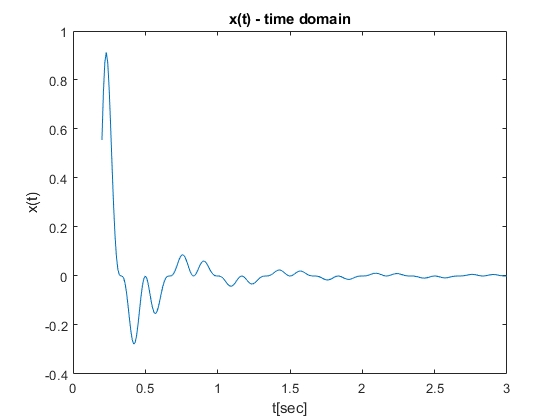

plot(t,x(t));title ('x(t) - time domain'); ylabel('x(t)'); xlabel('t[sec]')

we are asked to display the absulute value $\left|x\left(t\right)\right|$:

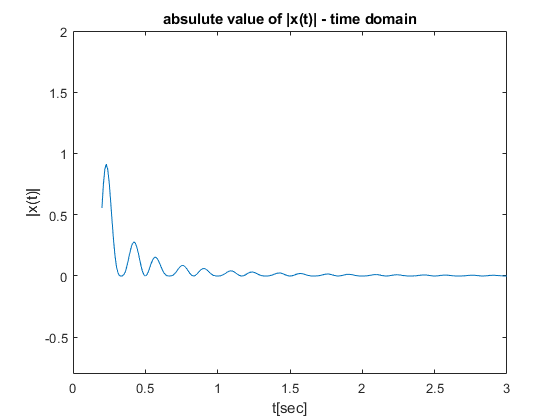


plot(t,abs(x(t)));title ('absulute value of |x(t)| - time domain'); ylabel('|x(t)|'); xlabel('t[sec]');
ylim([-0.8 2])

_____________________________________________________________________________


$$X\left(\omega \right)=\;\mathcal{F}\left\lbrace x\left(t\right)\right\rbrace$$



$$\;\;\;\;\;\;\;\;\;\;\;=\mathcal{F}\left\lbrace \frac{4}{\omega_m \pi t^2 }\cdot \sin^2 \left(\omega_m t\right)\cos \left(\omega_m t\right)\sin \left(2\omega_m t\right)\right\rbrace$$


here it is apropriate to use the convolution quality:

        
$$=\frac{4}{\omega_m \pi }\mathcal{F}\left\lbrace \frac{\sin \left(\omega_m t\right)}{t}\right\rbrace *\mathcal{F}\left\lbrace \frac{\sin \left(\omega_m t\right)}{t}\right\rbrace *\mathcal{F}\left\lbrace \sin \left({2\omega }_m t\right)\right\rbrace *\mathcal{F}\left\lbrace \cos \left(\omega_m t\right)\right\rbrace$$



$$=\frac{4}{\pi \omega_m }\left\lbrack \Pi \left(\frac{\omega }{{2\omega }_m }\right)*\Pi \left(\frac{\omega }{{2\omega }_m }\right)\right\rbrack *\left\lbrack \pi \left(\delta \left(\omega -2\omega_m \right)-\delta \left(\omega +2\omega_m \right)\right)*\pi \left(-i\right)\left(\delta \left(\omega -\omega_m \right)+\delta \left(\omega +\omega_m \right)\right)\right\rbrack$$


notice that convolving with dirac's deltas is equivalent to time shifting:


$$=-\frac{4}{{\pi \omega }_m }i\left\lbrack \Lambda \left(\frac{\omega }{{2\omega }_m }\right)\right\rbrack *\left\lbrack -\pi i\left(\delta \left(\omega -2\omega_m \right)-\delta \left(\omega +2\omega_m \right)\right)\right\rbrack \;*\left\lbrack \pi \left(\delta \left(\omega -\omega_m \right)+\delta \left(\omega +\omega_m \right)\right)\right\rbrack$$



$$=\frac{1}{\omega_m }\left\lbrack \Lambda \left(\frac{\omega -2\omega_m }{2\omega_m }\right)-\Lambda \left(\frac{\omega +2\omega_m }{{2\omega }_m }\right)\;\right\rbrack *\pi \left(\delta \left(\omega -\omega_m \right)+\delta \left(\omega +\omega_m \right)\right)$$



$$X\left(\omega \right)=\frac{\pi }{\omega_m }\left\lbrack \Lambda \left(\frac{\omega -3\omega_m }{{2\omega }_m }\right)+\Lambda \left(\frac{\omega -\omega_m }{2\omega_m }\right)-\Lambda \left(\frac{\omega +3\omega_m }{{2\omega }_m }\right)-\Lambda \left(\frac{\omega +\omega_m }{2\omega_m }\right)\right\rbrack$$


we got four lambda signals in frequency domain.

_____________________________________________________________________________________________

from the above expression it is clear that $X\left(\omega \right)$ ranges from $\omega \;=\;-5\pi$ up to $5\pi$ in frequancy domain.

meaning $X\left(\textrm{𝜔}\right)=0\;\;\forall \left|\textrm{𝜔}\right|\ge 5\pi$.

said realizaton provides us with sufficient terms for sampling in *Nyquist rate.*

*here we will use: *${\omega_s =\;\omega }_{\textrm{nyquist}} =2\omega_{\max } =10\omega_m$  

let's sample the signal

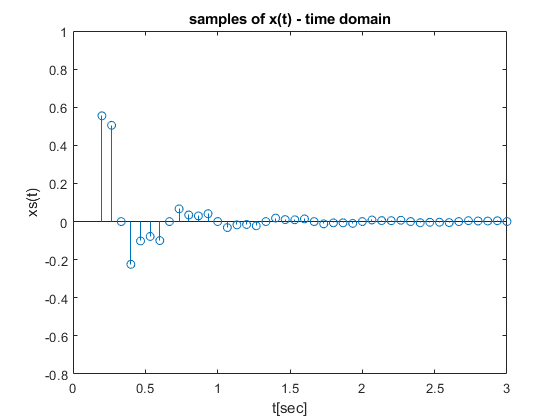

ws = 10 * wm;
Ts = 2*pi/(ws);
pT = 0.2:Ts:3;
N = 0:(floor(3/Ts)+1);

xs = x(pT);
stem(pT,xs) ;title ('samples of x(t) - time domain'); ylabel('xs(t)'); xlabel('t[sec]');
ylim([-0.8 1])

now we will implement a zero order hold:

x_ZOH = xs(floor((t-0.2)/Ts)+1);
plot(t,x_ZOH); title ('x(t) - through a ZOH'); ylabel('ZOH{x(t)}'); xlabel('t[sec]');
ylim([-0.8 1])

we will display them both on one grid:

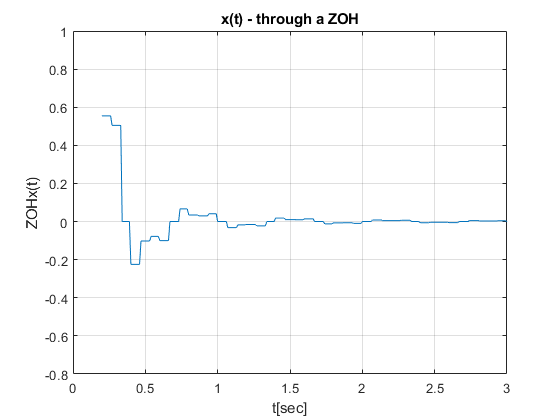

grid on;

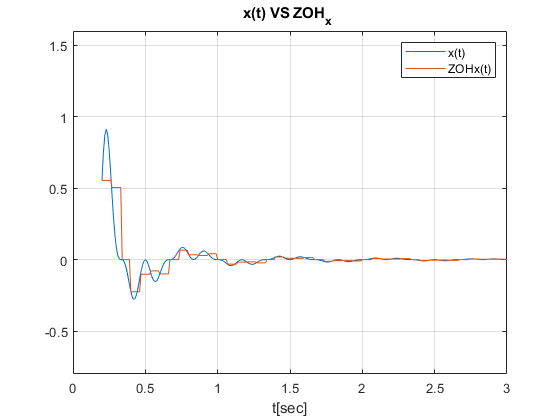

plot(t,x(t));
hold on
plot(t,x_ZOH);
title ('x(t) VS ZOH_x '); legend('x(t)','ZOH{x(t)}'); xlabel('t[sec]');
ylim([-0.8 1.6])
grid on;
hold off;

_____________________________________________________________________________


$$X_{\textrm{ZOH}} \left(\omega \right)=\;\mathcal{F}\left\lbrace x_{\textrm{ZOH}} \left(t\right)\right\rbrace$$


                
$$=\;\mathcal{F}\left\lbrace \sum_{n=0}^{\infty } x\left(n\cdot T_s \right)\cdot \Pi \left(\frac{t-\left(n+\frac{1}{2}T_s \right)}{T_s }\right)\right\rbrace$$


                        
$$=\;\sum_{n=0}^{\infty } x\left(n\cdot T_s \right)\cdot \;\mathcal{F}\left\lbrace \Pi \left(\frac{t-\left(\left(n+\frac{1}{2}\right)T_s \right)}{T_s }\right)\right\rbrace$$


                        
$$=\;\sum_{n=0}^{\infty } x\left(n\cdot T_s \right)\cdot e^{-i\;n\omega } \;\mathcal{F}\left\lbrace \Pi \left(\frac{t-\frac{1}{2}T_s }{T_s }\right)\right\rbrace$$


                       
$$=\mathcal{F}\left\lbrace \Pi \left(\frac{t-\frac{1}{2}T_s }{T_s }\right)\right\rbrace \;\sum_{n=0}^{\infty } x\left(n\cdot T_s \right)\cdot e^{-i\;n\cdot T_s \omega } \;$$


here we may recognize a familliar form:

  $\sum_{n=0}^{\infty } x\left(n\cdot T_s \right)\cdot e^{-i\;\left(n\cdot T_s \right)\omega } \;$ is no other then then the DTFT of the sampled x(t) signal!


$$=X_P \left(\omega \right)$$


 
$$X_{\textrm{ZOH}} \left(\omega \right)=\mathcal{F}\left\lbrace \Pi \left(\frac{t-\frac{1}{2}T_s }{T_s }\right)\right\rbrace \;X_P \left(\omega \right)$$


                    
$$={\mathcal{e}}^{-i\cdot \;\frac{1}{2}T_s \cdot \omega } \mathcal{F}\left\lbrace \Pi \left(\frac{t}{T_s }\right)\right\rbrace \;X_P \left(\omega \right)$$


                    
$$={\mathcal{e}}^{-i\cdot \;\frac{1}{2}T_s \cdot \omega } T\cdot \textrm{sinc}\left(\frac{\omega }{\omega_s }\right)X_P \left(\omega \right)$$


                    = ${\mathcal{e}}^{-i\cdot \;\frac{1}{2}T_s \cdot \omega } T\cdot \textrm{sinc}\left(\frac{\omega }{\omega_s }\right)\frac{1}{T}\sum_{n=-\infty }^{\infty } X\left(\omega -{n\omega }_s \right)\;$

                    
$${=\;\mathcal{e}}^{-i\cdot \;\frac{1}{2}T_s \cdot \omega } \cdot \textrm{sinc}\left(\frac{\omega }{\omega_s }\right)\sum_{n=-\infty }^{\infty } X\left(\omega -{n\omega }_s \right)\;$$


without further a due, we shall represent $X_{\textrm{ZOH}} \left(\omega \right)$in our code.we already have most of the needed input, so it will be a good idea to use this form:


$$X_{\textrm{ZOH}} \left(\omega \right)={=\;\mathcal{e}}^{-i\cdot \;\frac{1}{2}T_s \cdot \omega } \cdot \textrm{sinc}\left(\frac{\omega }{\omega_s }\right)\sum_{n=-\infty }^{\infty } X\left(\omega -{n\omega }_s \right)\;\;$$


w = -17*pi:1/100:17*pi;
TRI = @(w,s) triangularPulse((w+s*wm)/(2*wm));

X = @(w) -1i*(TRI(w,-3)+TRI(w,-1)-TRI(w,1)-TRI(w,3));
%plot(w,X(w)); title ('X(w)- frequancy domain'); ylabel('X(w)'); xlabel('w[sec-1]');



for now we have $X\left(\omega \right)$  correctly, $X_p \left(\omega \right)$ would be duplications of it:

X_P = @(w) (pi/wm)*(X(w-ws) +X(w) +X(w+ws));

time_shift = @(w) exp(-1i*0.5*Ts*w);

X_ZOH = time_shift(w).*sinc(w/ws).*X_P(w);

plot(w,X_ZOH); title ('X ZOH(w)- frequancy domain'); ylabel('ZOH{X(w)}'); xlabel('w[sec-1]');

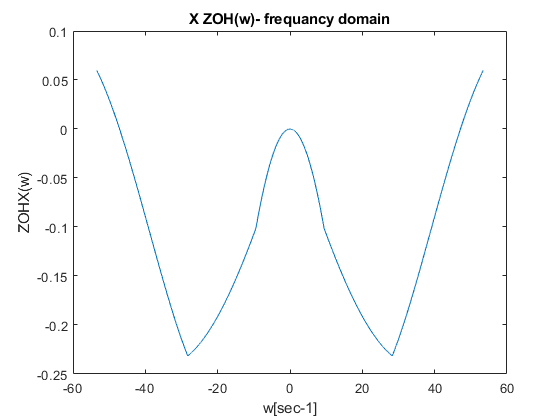

hold off

now let's see the absulute value of $X_{\textrm{ZOH}} \left(\omega \right)$

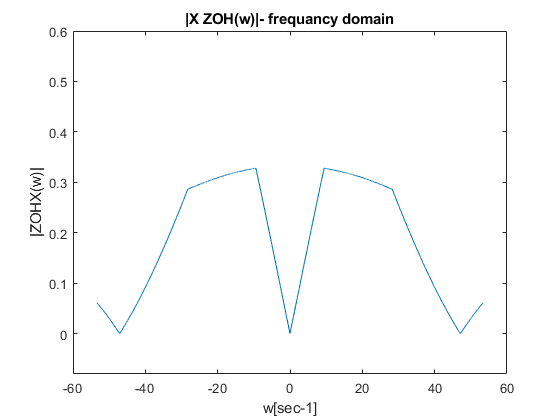

plot(w,abs(X_ZOH)); title ('|X ZOH(w)|- frequancy domain'); ylabel('|ZOH{X(w)}|'); xlabel('w[sec-1]');
ylim([-0.08 0.6])

_____________________________________________________________________

HEA

let us define $H\left(\omega \right)$:

filter = @(w) exp(1i*pi*w/ws)/(sinc(w/ws));
H = @(w) (filter(w))*(abs(w) < (ws/2));



now is the time to multiply $H\left(\omega \right)$ with $X_{\textrm{ZOH}} \left(\omega \right)$ to get the filterd signal:

X_rec =  H(w).*X_ZOH;
plot(w, X_rec);title ('X ZOH(w)H(w) - frequancy domain'); ylabel('|H {ZOH{X(w)}}|'); xlabel('w[sec-1]');

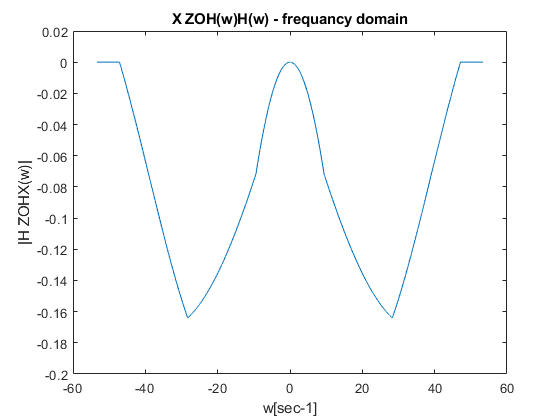

ylim([-0.2 0.02])

as we can see here, all other clones of $X\left(\omega \right)$ are eliminated, and only the one around $\omega =0$ has an effect.

now, the inverse fourier transfom shuld return the original signal x(t)

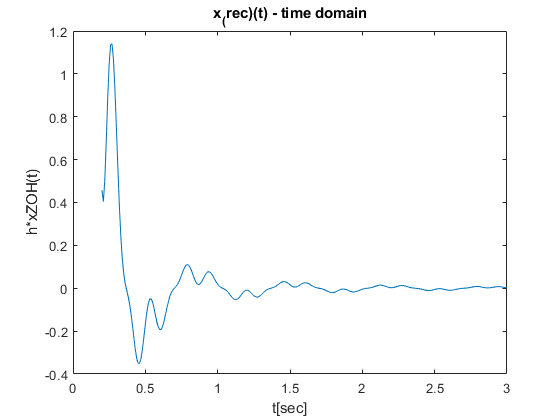

X_rec_eiwt =@(w,t) X_rec.*exp(1i*w*t);
x_rec =t;
for i = 1:size(t,2)
    x_rec(i) = trapz(w,X_rec_eiwt(w,t(i)));
end

plot(t,x_rec); title ('x_(rec)(t) - time domain'); ylabel('h*xZOH(t)'); xlabel('t[sec]');

lets plot $x_{\textrm{rec}} \left(t\right)\;$ and the original $x\left(t\right)$ toether:

plot(t,x_rec,'--', t, x(t)); title ('x_rec(t) VS x(t) - time domain'); ylabel('h*xZOH(t)'); xlabel('t[sec]');

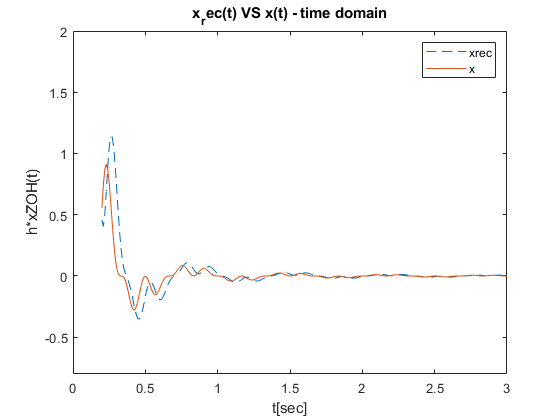

legend('xrec' , 'x')
ylim([-0.8 2])

a little comment deep from the heart might be in place here. the signal *shuld have *mached percisely its recoverd form. both theory, and specific calculations show that, and we brought them bothhere in our work. but after hours and hours of debugging i can say that I lost my left and right trying to find the bug causing the mismatch, without success. my hatred for matlab has meanwhile grew to a ranging fire, that burns with the fierce passion of a million suns. we know what to expact, and are **confident** enough in the studied material to say: there is an error. and it suld be confessed. matlab is not my favourite coding platform.

__________________________________________________________________

of curse $x\left(t\right)$ cannot be recoverd from equaly spaced samples at sampling rate $\omega_s \;$because such sub-nyquist rate would cause *aliasing *in $X_p \left(\omega \right)$

ws = 9*wm;
X_P = @(w) (1/3)*(X(w-ws) +X(w) +X(w+ws));

time_shift = @(w) exp(-1i*0.5*(2*pi/ws)*w);

X_ZOH = time_shift(w).*sinc(w/ws).*X_P(w);

filter = @(w) exp(1i*pi*w/ws)/(sinc(w/ws));
H = @(w) (filter(w))*(abs(w) <= (ws/2));

X_rec =  H(w).*X_ZOH;
X_rec_eiwt =@(w,t) X_rec.*exp(1i*w*t);
x_rec =t;

for i = 1:size(t,2)
    x_rec(i) = trapz(w,X_rec_eiwt(w,t(i)));
end

plot(t,x_rec,'--', t, x(t)); title ('x_rec(t) VS x(t) - time domain'); ylabel('h*xZOH(t)'); xlabel('t[sec]');

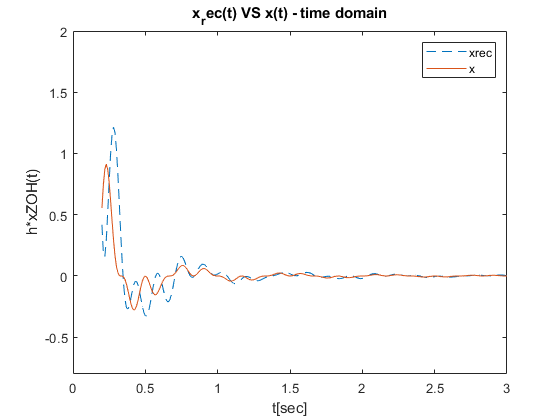

legend('xrec' , 'x')
ylim([-0.8 2])